## MAS 416 - Lecture 4 - Problem 2

clc; clear all; close all;

rho = 850; % kg/m^3
g = 9.81; % m/s^2


$$\begin{array}{l}
\beta =900\frac{N}{{\mathrm{mm}}^2 }\\
{10}^6 \;{\mathrm{mm}}^2 =m^2 \;\Longrightarrow \frac{{10}^6 \;{\mathrm{mm}}^2 }{m^2 }\\
\beta =900\frac{N}{{\mathrm{mm}}^2 }\cdot \frac{{10}^6 \;{\mathrm{mm}}^2 }{m^2 }=900\cdot {10}^6 \frac{N}{\mathrm{m²}}
\end{array}$$


beta = 900*10^6; % N/m^2
Cd = 0.55; % -


$$\begin{array}{l}
A_d =15\mathrm{mm²}\\
10⁶\;\mathrm{mm²}=\mathrm{m²}\Longrightarrow \frac{m^2 }{{10}^6 \;\mathrm{mm²}}\\
A_d =15\mathrm{mm²}\cdot \frac{m^2 }{{10}^6 \;\mathrm{mm²}}=15\cdot {10}^{-6} \;\mathrm{m²}
\end{array}$$


Ad = 15*10^-6; % m^2


$$\begin{array}{l}
V_2 =2000{\mathrm{cm}}^3 \\
{10}^6 \;{\mathrm{cm}}^3 =m^3 \Longrightarrow \frac{m^3 }{{10}^6 \;\mathrm{cm³}}\\
V_2 =2000{\;\mathrm{cm}}^3 \cdot \frac{m^3 }{{10}^6 \;\mathrm{cm³}}=2000\cdot {10}^{-6} {\;m}^3 
\end{array}$$


d = 63/1000; % m, piston diameter
m = 3200; % kg, payload

V_2_min = 2000*10^-6; % m^3


$$\begin{array}{l}
V_{2_{\min } } =2000\;{\mathrm{cm}}^3 \\
{10}^6 \;{\mathrm{cm}}^3 =m^3 \Longrightarrow \frac{m^3 }{{10}^6 \;{\mathrm{cm}}^3 }\\
V_{2_{\min } } =2000\;{\mathrm{cm}}^3 \cdot \frac{m^3 }{{10}^6 \;{\mathrm{cm}}^3 }=2000\cdot {10}^{-6} \;m^3 
\end{array}$$


y = 0; % Payload height at rest
yDot = 0; % Cylinder speed at rest
A = pi/4 * d^2; % Area of piston
p_2_init = (m*g)/A; % Pa (N/m^2), mass*gravity = F, p = F/A


$$\begin{array}{l}
p_{1_{\max } } =150\;\mathrm{bar}\\
1\;\mathrm{bar}={10}^5 \;\mathrm{Pa}\Longrightarrow \frac{10⁵\;\mathrm{Pa}}{\mathrm{bar}}\\
p_{1_{\max } } =150\;\mathrm{bar}\cdot \frac{10⁵\;\mathrm{Pa}}{\mathrm{bar}}=150\cdot {10}^5 \;\mathrm{bar}
\end{array}$$


p_1_max = 150 * 10^5; % Pa
t_ramp = 0.3; % s

simTime = 1; % s
t = 0; % s
dt = 10^-3; % Timestep resolution
idx = 1; % Counter

p1 = 0; % Pa
p2 = p_2_init; % Pa

while t <= simTime
    % Generate ramp for p1
    if(t <= t_ramp)
    p1 = t/t_ramp * p_1_max; % If the time is between 0 and 0.3s, then create ramp
    else
    p1 = p_1_max; % When ramp time is completed, then the p1 pressure is constant
    end

Formula for $Q$:

   
$$Q_{P\rightarrow A} = C_d \cdot A_d \cdot SIGN\left(\sqrt{\Delta p}\right) \cdot \sqrt{\frac{2}{\rho} \cdot |(p_P - p_A)|}$$


    Q = Cd * Ad * sign(p1-p2)*sqrt(2/rho * abs(p1-p2)); % Numeric representation of orifice equation Q

    Formula for $\dot{p_2 }$:


$$\dot{p} = \frac{\beta}{V}\cdot \sum Q_i-\dot{V}$$


$\dot{p} =\frac{\beta }{V}\cdot \left(Q_1 +Q_2 -Q_3 -Q_4 -A\cdot v\right)$, where A is the area of a cylinder and v is the speed of the cylinder

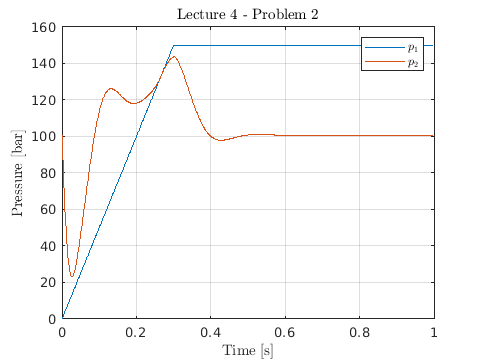

    % Calculating the volume V_2 by summing the initial volum with
    % the change in volume as time goes by.
    V_2 = V_2_min + A * y;

    % Equation for p2Dot is found on slide 8, lecture 4.
    p2Dot = (beta/V_2)*(Q-(A*yDot));
    yDotDot = (A*p2-m*g)/m; % p = F/A ==> F = p*A
                            % yDotDot = y'' = a
                            % F = m*a ==> a = F/m

    % Logging
    timePlot(idx) = t;
    p1Plot(idx) = p1/10^5;
    p2Plot(idx) = p2/10^5;
    yPlot(idx) = y;
    yDotPlot(idx) = yDot;
    yDotDotPlot(idx) = yDotDot;

    % Time integrate
    p2 = p2 + p2Dot * dt;
    y = y + yDot * dt;
    yDot = yDot + yDotDot * dt;

    % p2 can not be in vaccum
    if(p2<0)
        p2 = 0;
    end

    % Update variables
    idx = idx + 1;
    t = t + dt;
end

% Plot results
% Pressure plots
plot(timePlot, p1Plot)
hold on
plot(timePlot, p2Plot)
ylim([0 160])
xlabel("Time [s]", 'interpreter','latex')
ylabel("Pressure [bar]", 'interpreter','latex')
title("Lecture 4 - Problem 2", 'interpreter','latex')
legend('$p_1$', '$p_2$', 'interpreter','latex')
grid on

% Position and velocity plots
hold off

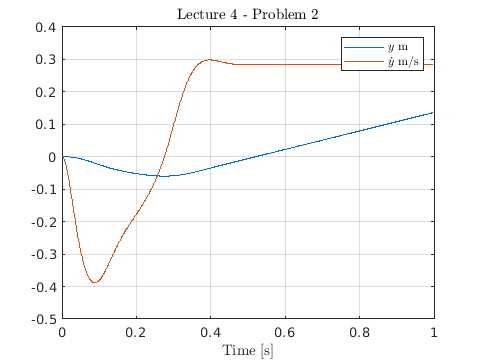

plot(timePlot, yPlot)
hold on
plot(timePlot, yDotPlot)
%plot(timePlot, yDotDotPlot)
ylim([-0.5 0.4])
xlabel("Time [s]", 'interpreter','latex')
%ylabel("Pressure [bar]", 'interpreter','latex')
title("Lecture 4 - Problem 2", 'interpreter','latex')
legend('$y$ m', '$\dot{y}$ m/s', 'interpreter','latex')
grid on